## Procesamiento de datos

data = readmatrix('Flujo_delta_25a50.xlsx')

data =    20.0605   25.0000    7.5147
   20.0870   25.0000    7.8209
   20.1135   25.0000    7.6678
   20.1400   25.0000    8.1781
   20.1665   25.0000    7.7698
   20.1930   25.0000    8.0760
   20.2195   25.0000    8.1781
   20.2460   25.0000    8.2291
   20.2725   25.0000    8.5352
   20.2990   25.0000    8.5352


data = readmatrix('Flujo_delta_25a50.xlsx','Range','A377:C1471')

data =    30.0245   25.0000   20.5266
   30.0510   25.0000   20.2205
   30.0775   25.0000   20.4756
   30.1040   25.0000   20.1695
   30.1305   25.0000   20.6797
   30.1570   25.0000   20.1184
   30.1835   25.0000   20.3225
   30.2100   25.0000   19.9653
   30.2365   25.0000   20.2205
   30.2630   25.0000   19.5571


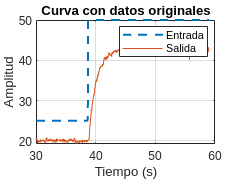


t = data(:,1);
u = data(:,2);
y = data(:,3);


yn = y - mean(y(1:10));
un = u - mean(u(1:10));


figure(1)
plot(t, u,'--', LineWidth=1.5)
hold on
plot(t, y);
title('Curva con datos originales')
legend('Entrada', 'Salida')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

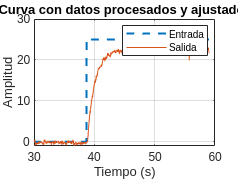


figure(2);
plot(t, un,'--', LineWidth=1.5)
hold on
plot(t, yn);
title('Curva con datos procesados y ajustados')
legend('Entrada', 'Salida')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

## System Identification Tool

%systemIdentification

## Identificación 123c Alfaro Primer orden con retardo

yf = mean(yn(1085:1095))

yf = 22.5397

yi = mean(yn(1:10))

yi = -3.5527e-15


uf = mean(un(1085:1095))

uf = 25

ui = mean(un(1:10)) 

ui = 0


deltay = yf - yi

deltay = 22.5397


deltau = uf - ui

deltau = 25


K = deltay/deltau

K = 0.9016


y25 = 0.25*deltay

y25 = 5.6349

y25_0 = find(yn >= y25, 1) 

y25_0 = 346

t25 = t(y25_0)

t25 = 39.1670


y50 = 0.50*deltay;
y50_0 = find(yn >= y50, 1) 

y50_0 = 365

t50 = t(y50_0)

t50 = 39.6705


y75 = 0.75*deltay;
y75_0 = find(yn >= y50, 1) 

y75_0 = 365

t75 = t(y75_0)

t75 = 39.6705



T = 0.9102*(t75 - t25)

T = 0.4583

L = 1.2620*t25 - 0.2620*t75

L = 39.0351